[~,folder,~] = fileparts(pwd);
assert(strcmpi(folder,"non-ferromagnetic metal plate with hole in frequency domain"), 'Not in project directory')
addpath('../../DCS_functions')

clear

## Distributed Current Source

#### Coil

Coil.num = 1;
Coil.inner_radius = 3.75e-3; % (m)
Coil.outer_radius = 6.00e-3; % (m)
Coil.length       = 4.00e-3; % (m)

Coil.wire_diameter = 0.35e-3; % (m)
Coil.N_turns = 60;
Coil.conductivity = 6e7; % (S/m)

Coil_pos = [-10e-3 -5e-3 4e-3]; % (m)
Coil = SetPositionRotation3D(Coil, Coil_pos.', [1 0 0].', deg2rad(0));
clear Coil_pos

#### Sensor

Sensor.num = 40;
Sensor.side_length = 0.5e-3;

Sensor_pos = [
    linspace(-30e-3,30e-3,Sensor.num); 
     -5e-3       * ones(1,Sensor.num); 
    1.5e-3       * ones(1,Sensor.num) ];
Sensor = SetPositionRotation3D(Sensor, Sensor_pos);
clear Sensor_pos

#### Model (element conductivity set to zero at hole)

plate.l = 60e-3; % (m)
plate.h = 2e-3;  % (m)
plate.n_l = 30; % number of elements in x and y direction

x = linspace(-plate.l/2, plate.l/2, plate.n_l+1);
y = x;
z = [-plate.h 0];

Model = BuildModel3D('Cuboid', x,y,z, 'hexahedron');

build model took 0.08 seconds



Model.conductivity = 3.774e7 * ones(1,Model.num_elems); % (S/m)
for i = 1:Model.num_elems
    x = Model.elems_center(1,i);
    y = Model.elems_center(2,i);
    if -10e-3 < x && x < 10e-3   &&   -10e-3 < y && y < 10e-3
        Model.conductivity(i) = 0;
    end
end

Model.relative_permittivity = 1 * ones(1,Model.num_elems); % (1)
Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)

clear plate x y z i

#### Model (actual hole)

% node_file  = 'square-with-hole_node.txt';
% element_file = 'square-with-hole_element.txt';
% Model = BuildModel3D('Extrude', node_file, element_file, 1, [-2e-3 0]);
% 
% Model.conductivity = 3.774e7 * ones(1,Model.num_elems); % (S/m)
% Model.relative_permittivity = 1 * ones(1,Model.num_elems); % (1)
% Model.relative_permeability = 1 * ones(1,Model.num_elems); % (1)
% 
% clear node_file element_file

#### Governing equation

GoverningEquation = BuildGoveringEquation3D(Model, Coil, Sensor);

build governing equation took 4.44 seconds


#### Solve in frequency domain

V_E = readmatrix('FEA_data/V_E.csv', 'CommentStyle','%');
V_E = V_E(4);
Coil.frequency_domain.excitation = {"Voltage" V_E}; % (V)
clear V_E

% Coil.frequency_domain.excitation = {"Current" 1}; % (A)

Coil.frequency_domain.frequency = 1000; % (Hz)
[Model, Coil, Sensor] = SolveFrequencyDomain3D(GoverningEquation, Model, Coil, Sensor);

solve in frequency domain took 1.73 seconds


#### Plot world

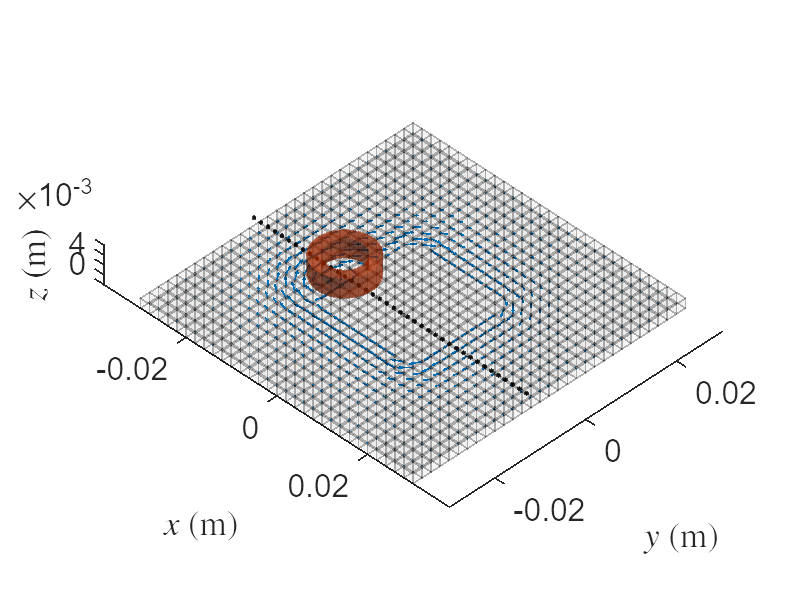

r = Model.elems_center;
J = real(Model.frequency_domain.J);

figure
PlotWorld3D(Model, Coil, Sensor)
quiver3(r(1,:),r(2,:),r(3,:), J(1,:),J(2,:),J(3,:))


clear r J

## Compare with FEA

#### Eddy current density

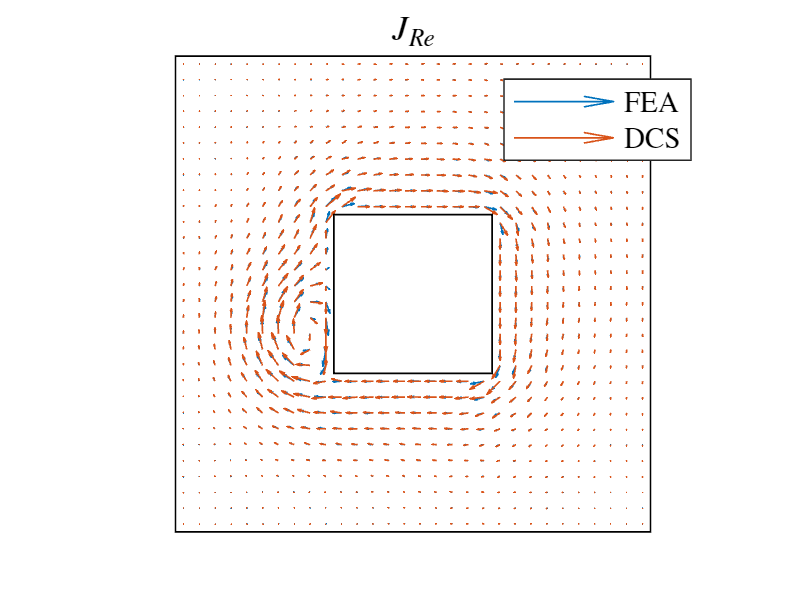

data = readmatrix('FEA_data/J.txt', 'CommentStyle','%');
FEA.x  = data(:,1);
FEA.y  = data(:,2);
FEA.Jx = data(:,4);
FEA.Jy = data(:,5);
FEA.Jz = data(:,6);
clear data

x = Model.elems_center(1,:);
y = Model.elems_center(2,:);

figure
hold on
quiver(FEA.x, FEA.y, real(FEA.Jx), real(FEA.Jy), 'DisplayName','FEA');
quiver(x, y, real(Model.frequency_domain.J(1,:)), real(Model.frequency_domain.J(2,:)), 'DisplayName','DCS');
rectangle('Position',[-30e-3 -30e-3 60e-3 60e-3])
rectangle('Position',[-10e-3 -10e-3 20e-3 20e-3])
title('$J_{Re}$', 'Interpreter','latex')
legend('show', 'Location','northeast', 'Interpreter','latex');
axis equal off

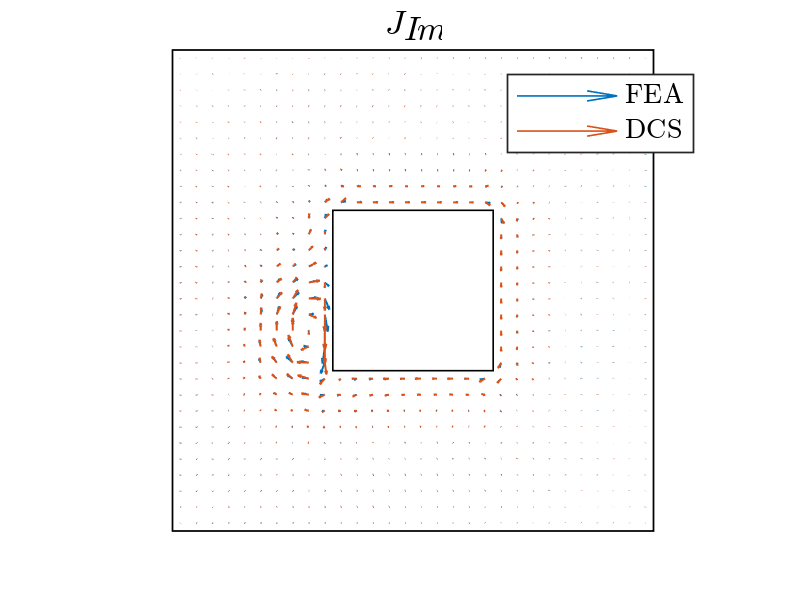


figure
hold on
quiver(FEA.x, FEA.y, imag(FEA.Jx), imag(FEA.Jy), 'DisplayName','FEA');
quiver(x, y, imag(Model.frequency_domain.J(1,:)), imag(Model.frequency_domain.J(2,:)), 'DisplayName','DCS');
rectangle('Position',[-30e-3 -30e-3 60e-3 60e-3])
rectangle('Position',[-10e-3 -10e-3 20e-3 20e-3])
title('$J_{Im}$', 'Interpreter','latex')
legend('show', 'Location','northeast', 'Interpreter','latex');
axis equal off


clear x y

#### Magnetic flux density

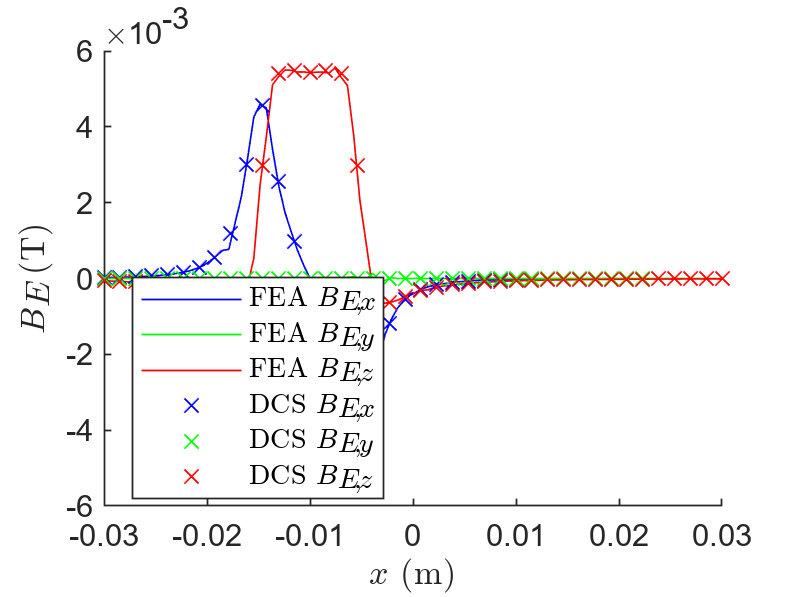

data = readmatrix('FEA_data/B.txt', 'CommentStyle','%');
FEA.x     = data(:,1);
FEA.B_E_x = data(:,7);
FEA.B_E_y = data(:,8);
FEA.B_E_z = data(:,9);
FEA.B_C_x = data(:,4) - FEA.B_E_x;
FEA.B_C_y = data(:,5) - FEA.B_E_y;
FEA.B_C_z = data(:,6) - FEA.B_E_z;
clear data

figure
hold on
plot(FEA.x, real(FEA.B_E_x), 'b-', 'DisplayName','FEA $B_{E,x}$')
plot(FEA.x, real(FEA.B_E_y), 'g-', 'DisplayName','FEA $B_{E,y}$')
plot(FEA.x, real(FEA.B_E_z), 'r-', 'DisplayName','FEA $B_{E,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(1,:)), 'bx', 'DisplayName','DCS $B_{E,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(2,:)), 'gx' ,'DisplayName','DCS $B_{E,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_E(3,:)), 'rx' ,'DisplayName','DCS $B_{E,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_E$ (T)", 'Interpreter','latex')

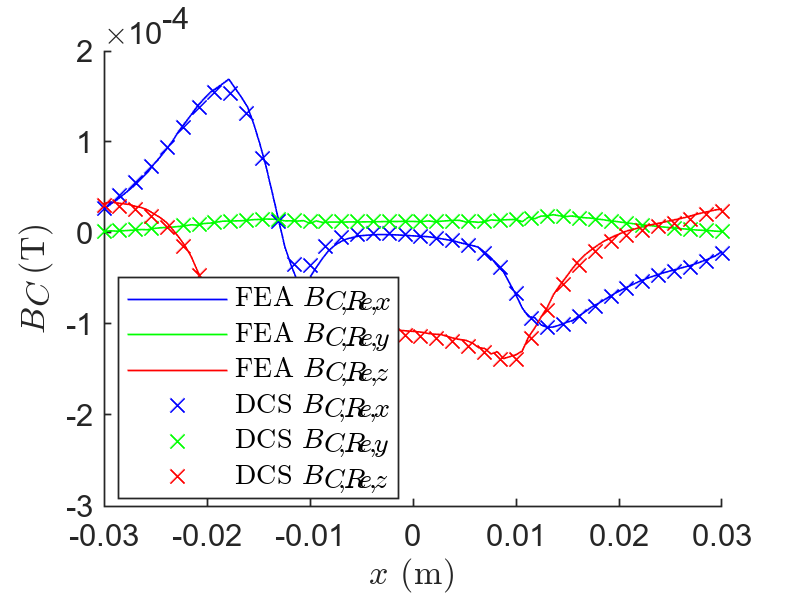


figure
hold on
plot(FEA.x, real(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Re,x}$')
plot(FEA.x, real(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Re,y}$')
plot(FEA.x, real(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Re,z}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Re,x}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Re,y}$')
plot(Sensor.position(1,:), real(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Re,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')

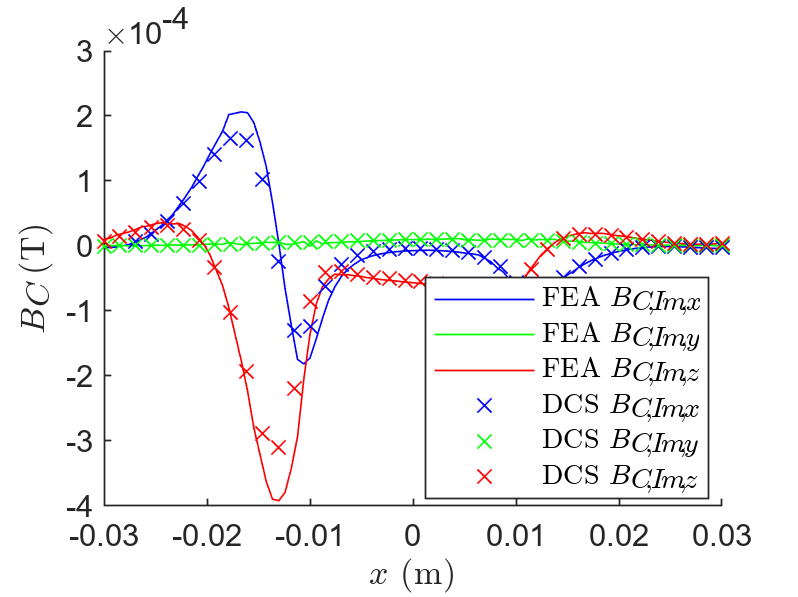


figure
hold on
plot(FEA.x, imag(FEA.B_C_x), 'b-', 'DisplayName','FEA $B_{C,Im,x}$')
plot(FEA.x, imag(FEA.B_C_y), 'g-', 'DisplayName','FEA $B_{C,Im,y}$')
plot(FEA.x, imag(FEA.B_C_z), 'r-', 'DisplayName','FEA $B_{C,Im,z}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(1,:)), 'bx', 'DisplayName','DCS $B_{C,Im,x}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(2,:)), 'gx' ,'DisplayName','DCS $B_{C,Im,y}$')
plot(Sensor.position(1,:), imag(Sensor.frequency_domain.B_C(3,:)), 'rx' ,'DisplayName','DCS $B_{C,Im,z}$')
legend('show', 'Location','best', 'Interpreter','latex');
xlabel("$x$ (m)", 'Interpreter','latex')
ylabel("$B_C$ (T)", 'Interpreter','latex')